# Math 503B Homework 6 Ashley Jubb

## For the seismometer example with two pulses: Plot g(alpha) based on generalized cross validation for the first-order Tikhonov regularization problem. Find the optimal alpha using fminsearch. Plot the solution for this optimal alpha.

% make sure we have a clean environment
clear
rand('seed',0);
randn('seed',0);

% Find G matrix 
sigma=2;
t=linspace(-5,100,211);
mTrue=exp(-((t-8).^2/(2*sigma.^2))+0.5*exp(-((t-25).^2)/(2*sigma.^2)));
G=zeros(length(t), length(t));
for i=1:length(G)-1;
    delt=t(i+1)-t(i);
    for j=1:length(G)-1;
        if i>=j;
            G(i,j)= mTrue(i)*delt;
        else
            G(i,j)=0;
        end
    end
end

dspiken= (mTrue*G')';
mNoise=mTrue+ randn*mTrue;

% Calculate the svd
[U,S,V]=svd(G);
[M,n]= size(G);
s=diag(S);
alpha_min=min(s);
alpha_max=max(s);

[rho,eta,reg_param]=l_curve_tikh_svd(U,s,dspiken,n);
% estimate the L-curve corner in log-log space using a spline fit 
% to find where maximum negative curvature occurs(requires Spline Toolbox)
[alpha_tikh,ireg_corner] = l_curve_corner(rho,eta,reg_param);
rho_corner = rho(ireg_corner);
eta_corner = eta(ireg_corner);

% Compute the Tikhonov Regularization solution
% get the spike solution corresponding to the L-curve corner

G_tikh = G'*G+alpha_tikh*(1+.05*randn*sigma)^2*eye(n);
m_tikh = (G_tikh)\G'*dspiken;

% get the residual using the L-curve solution
r_spike = norm(G*m_tikh-dspiken);
d_tikh = G*m_tikh;

% get g(alpha) and plot
L=diag(-ones(1,n)) + diag(ones(1,n-1),1);
G_p = inv(G'*G + alpha_tikh^2*L'*L)*G';
m_al= G_p*dspiken;
g_alpha=((M*norm(G*m_al-dspiken))/(trace(eye(n)-G*G_p)).^2)

g_alpha = 0.0042

gcv= my_gcv(g_alpha, G_tikh,m_tikh,dspiken)

gcv = 373.8300


L1 = eye(n);
[U1,V1,X1,Lam1,Mu1] = gsvd(G,L1);
p = rank(L1);
lam = sqrt(diag(Lam1*Lam1));
mu = sqrt(diag(Mu1'*Mu1));
sm1 = [lam(1:p),mu(1:p)];

%find optimal alpha value using fminsearch and gcv
gcv_optal= @(alpha) my_gcv(alpha,G,S,dspiken)

gcv_optal = function_handle with value:
    @(alpha)my_gcv(alpha,G,S,dspiken)


optimum_alpha=fminsearch(gcv_optal,0.14)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.060642 



optimum_alpha = 0.1330

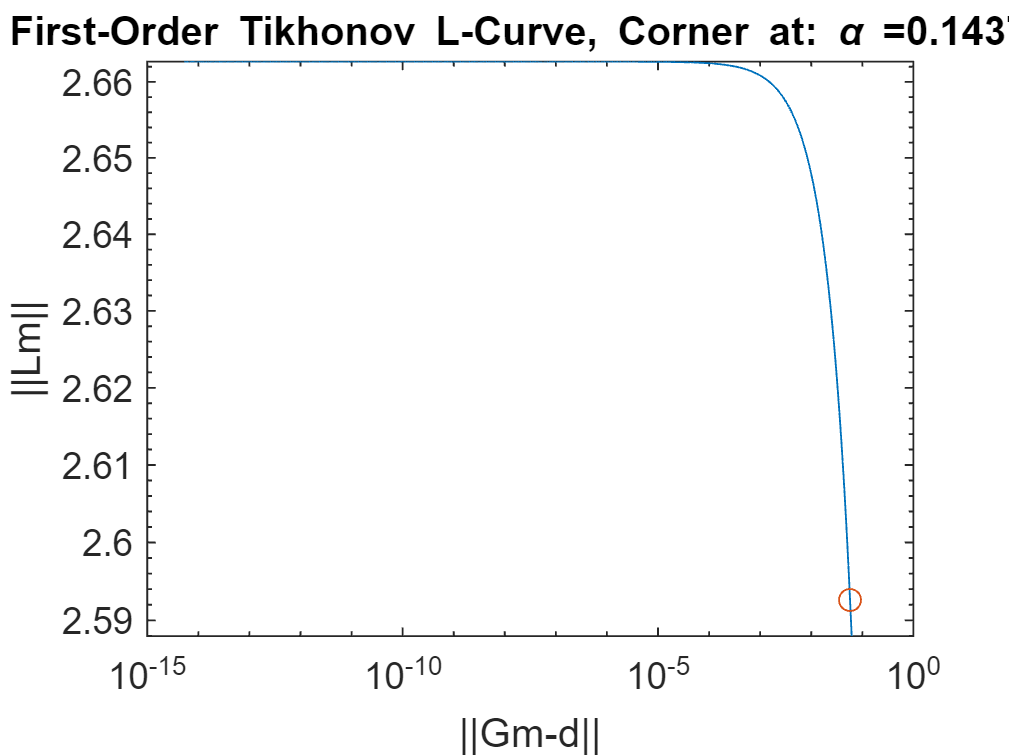


%find solution with optimal alpha from fminsearch and plot solutions 
m_optalpha=(inv(G'*G + optimum_alpha^2*L'*L)*G')*dspiken;
figure();
[rho,eta,reg_param]=l_curve_tikh_gsvd(U1,dspiken,X1,Lam1,Mu1,G,L1,1000,1e-10,0.15);
[alpha_corner,ireg_corner,kappa]=l_curve_corner(rho,eta,reg_param);
loglog(rho,eta)
hold on
loglog(rho(ireg_corner),eta(ireg_corner),'o')
hold off
xlabel('||Gm-d||')
ylabel('||Lm||')
title(['First-Order Tikhonov L-Curve, Corner at: \alpha =',num2str(alpha_corner)]);

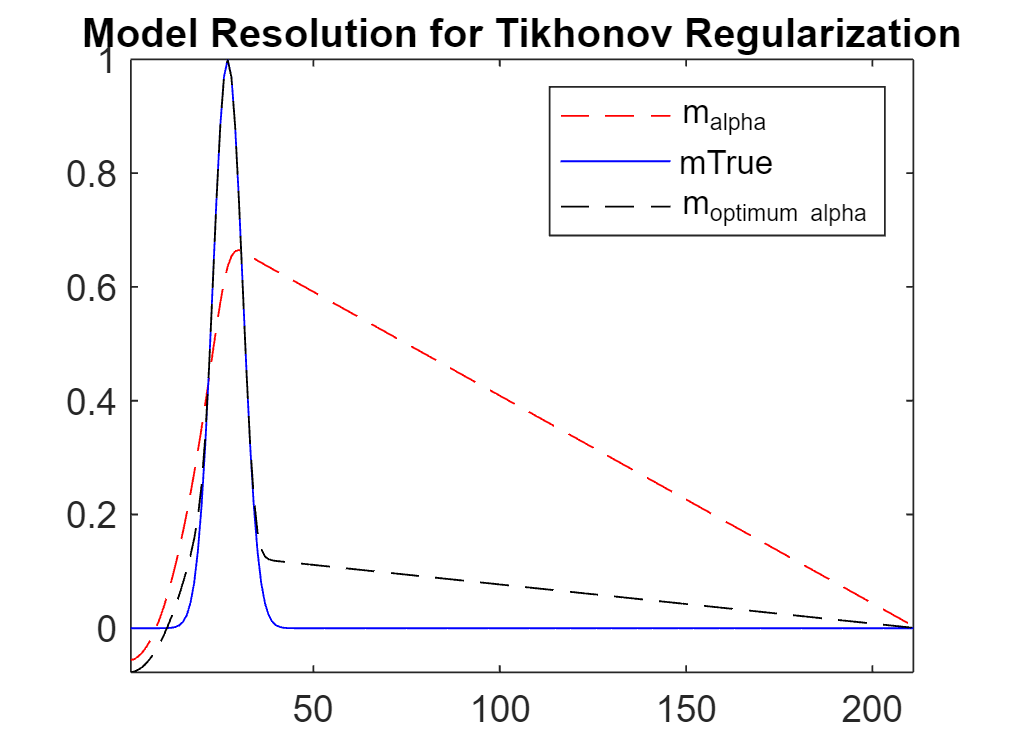

figure();
plot(m_al,'r--'); hold on;
plot(mTrue,'b');
plot(m_optalpha,'k--'); 
axis tight;
legend('m_{alpha}','mTrue','m_{optimum alpha}');
title('Model Resolution for Tikhonov Regularization')

function mygcv= my_gcv(alpha,G,S,dspiken)
sigma=2;
[M,n]= size(G);
G_tikh = G'*G+alpha*(1+.05*randn*sigma)^2*eye(n);
Gp= pinv(G_tikh)*G;
m_al= Gp*dspiken;
r=G*m_al-dspiken;
mygcv= ((M*norm(G*m_al-dspiken))/(trace(eye(n)-G*Gp)).^2);
end

